% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
% Communication Systems
% Computer Assignment 4 : (Statistics, Random Process and Quantization)
% Mohammad Mahdi Abdolhosseini
% Student Number: 810 198 434
% Winter 2022
% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
clc; clear; close all;

# `Part 1 : Statistics`

## `part 1:`

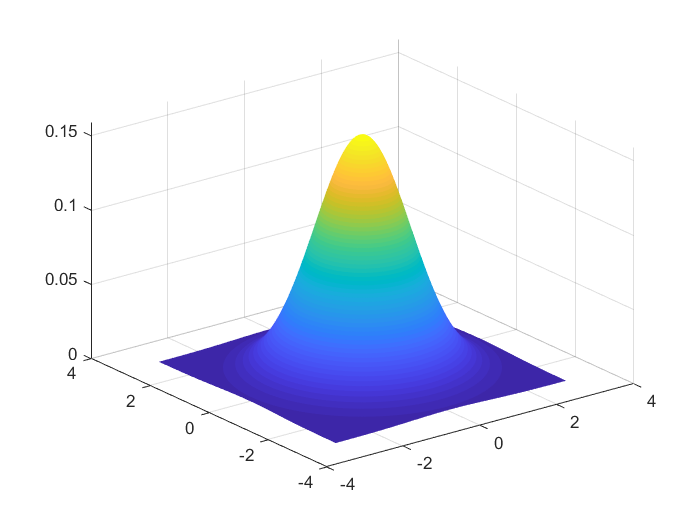

n = 3000;
t = linspace(-3,3,n);
X = normpdf(t,0,1); % X = 1/(sqrt(2*pi)) * exp(-t.^2/2)
Y = normpdf(t,0,1); % Y = 1/(sqrt(2*pi)) * exp(-t.^2/2)
s = surf(t,t,Y'*X);
set(s,'LineStyle','none');
grid on;

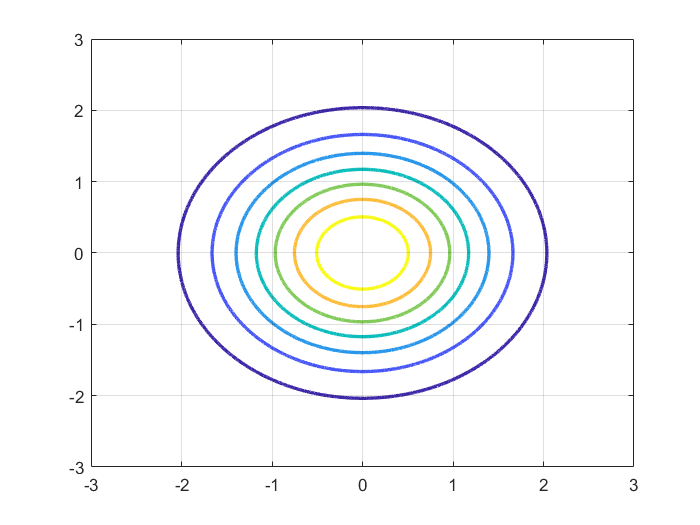

RContour(X,Y,t,t);

## `part 2:`

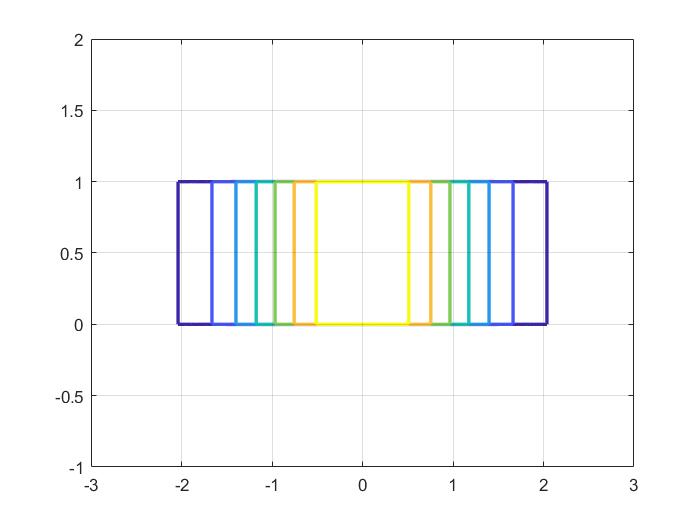

t2 = linspace(-1,2,n);
Y = unifpdf(t2);
RContour(X,Y,t,t2); % X = 1/(sqrt(2*pi)) * exp(-t.^2/2)

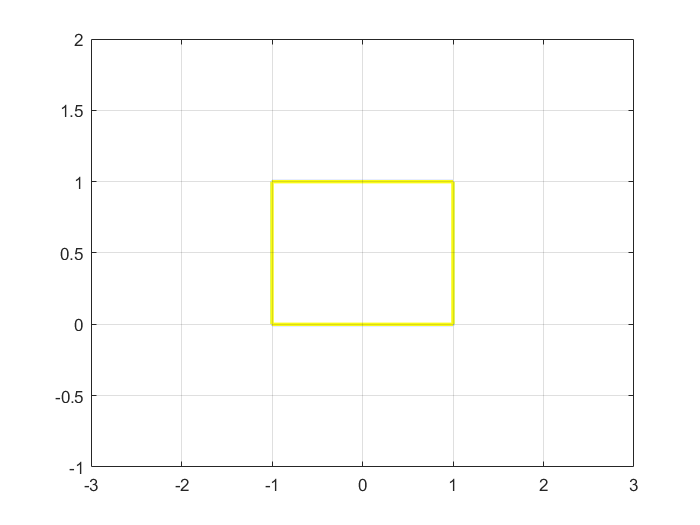

%=-=-=-=-=-=-=-=-=-=-=-=-=-=
X = unifpdf(t2);
Y = unifpdf(t2);
RContour(X,Y,t,t2);

# `Part 2 : Random Process`

## `part 2:3:`

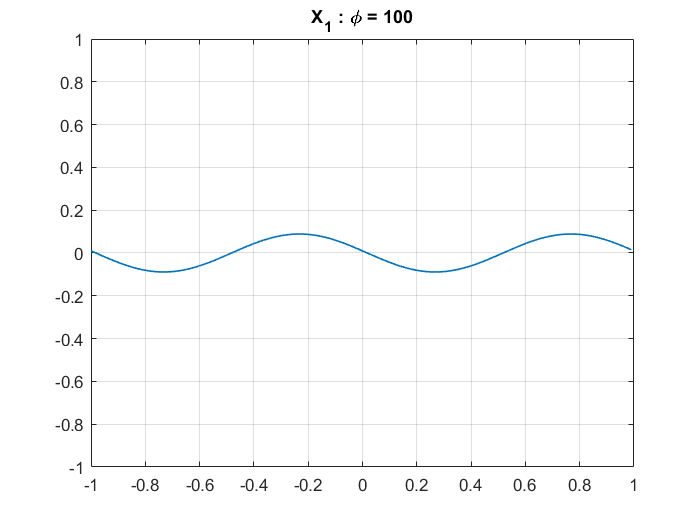

t = -1:0.01:1-0.01;
Lt = length(t);

n1 = 100;
n2 = 1000;
n3 = 10000;

% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=

x1_n1 = zeros(Lt,n1);
x1_n2 = zeros(Lt,n2);
x1_n3 = zeros(Lt,n3);

x1_n1_mean = zeros(1,Lt);
x1_n2_mean = zeros(1,Lt);
x1_n3_mean = zeros(1,Lt);

phi1_n1 = unifrnd(-pi,pi,[1,n1]);
phi1_n2 = unifrnd(-pi,pi,[1,n2]);
phi1_n3 = unifrnd(-pi,pi,[1,n3]);

% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=

x2_n1 = zeros(Lt,n1);
x2_n2 = zeros(Lt,n2);
x2_n3 = zeros(Lt,n3);

x2_n1_mean = zeros(1,Lt);
x2_n2_mean = zeros(1,Lt);
x2_n3_mean = zeros(1,Lt);

phi2_n1 = unifrnd(-pi/4,pi/4,[1,n1]);
phi2_n2 = unifrnd(-pi/4,pi/4,[1,n2]);
phi2_n3 = unifrnd(-pi/4,pi/4,[1,n3]);

% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=

for i=1:n3
    x1_n3(:,i) = cos(2*pi*t + phi1_n3(i));
    x2_n3(:,i) = cos(2*pi*t + phi2_n3(i));
    
    if (i<n2+1)
        x1_n2(:,i) = cos(2*pi*t + phi1_n2(i));
        x2_n2(:,i) = cos(2*pi*t + phi2_n2(i));
        
        if (i<n1+1)
            x1_n1(:,i) = cos(2*pi*t + phi1_n1(i));
            x2_n1(:,i) = cos(2*pi*t + phi2_n1(i));
        end
        
    end
    
end

for i = 1:Lt
    
    x1_n1_mean(i) = sum(x1_n1(i,:)) / n1;
    x1_n2_mean(i) = sum(x1_n2(i,:)) / n2;
    x1_n3_mean(i) = sum(x1_n3(i,:)) / n3;
    
    x2_n1_mean(i) = sum(x2_n1(i,:)) / n1;
    x2_n2_mean(i) = sum(x2_n2(i,:)) / n2;
    x2_n3_mean(i) = sum(x2_n3(i,:)) / n3;
    
end

% =-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=

plot(t,x1_n1_mean, 'linewidth', 1);
title('X_1 : \phi = 100');
set(gca,'ytick', -1 : 0.2 : 1, 'ylim', [-1,1]);
grid on;

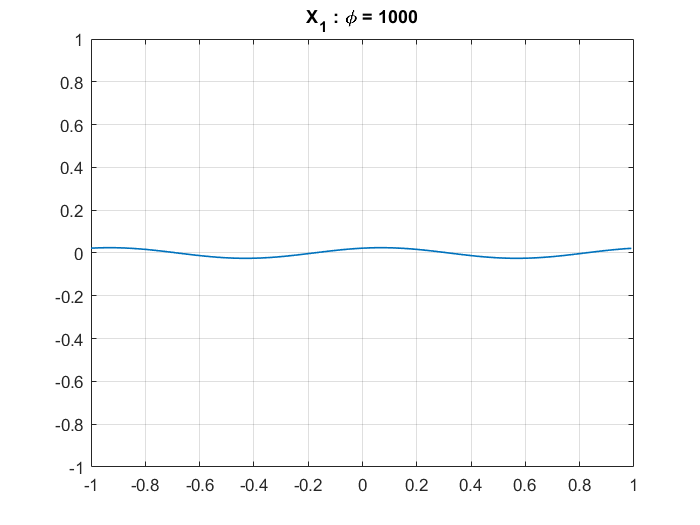


plot(t,x1_n2_mean, 'linewidth', 1);
title('X_1 : \phi = 1000');
set(gca,'ytick', -1 : 0.2 : 1, 'ylim', [-1,1]);
grid on;

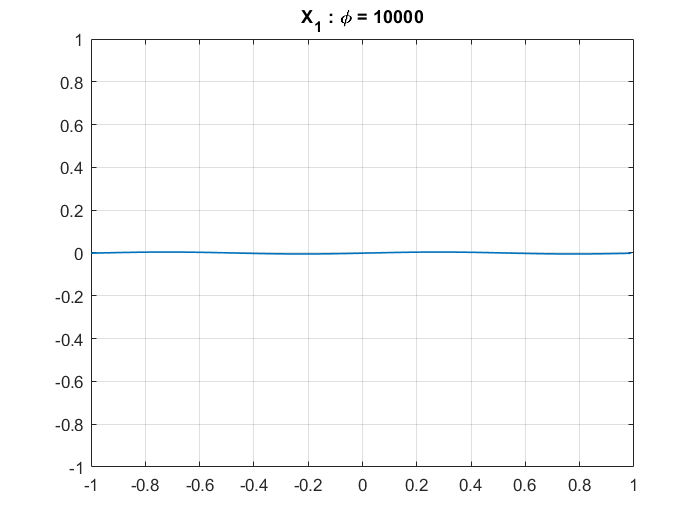


plot(t,x1_n3_mean, 'linewidth', 1);
title('X_1 : \phi = 10000');
set(gca,'ytick', -1 : 0.2 : 1, 'ylim', [-1,1]);
grid on;

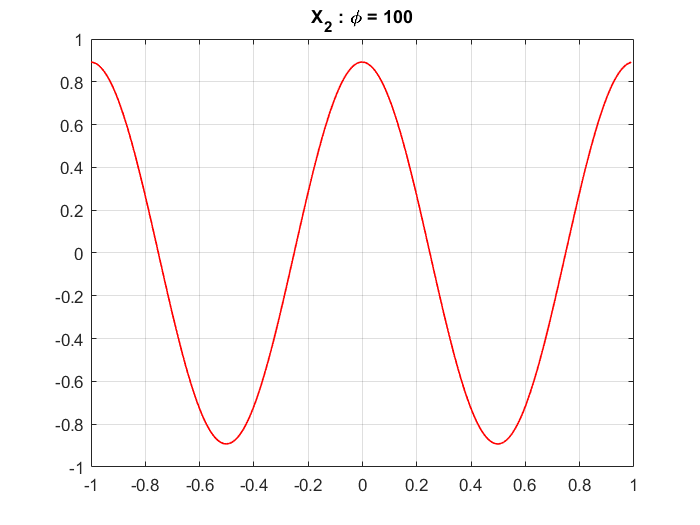


plot(t,x2_n1_mean, 'r', 'linewidth', 1);
title('X_2 : \phi = 100');
grid on;

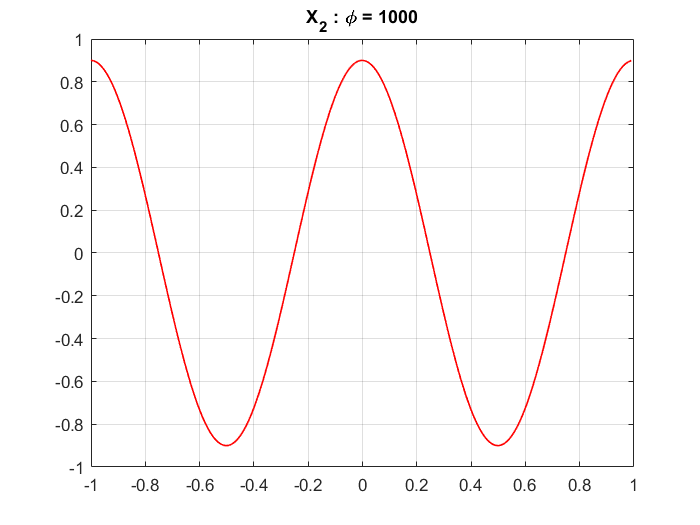


plot(t,x2_n2_mean, 'r', 'linewidth', 1);
title('X_2 : \phi = 1000');
grid on;

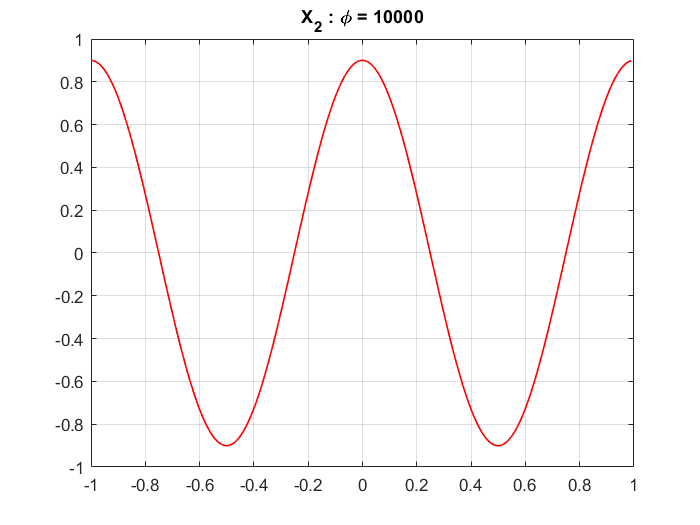


plot(t,x2_n3_mean, 'r', 'linewidth', 1);
title('X_2 : \phi = 10000');
grid on;

## `part 4:`

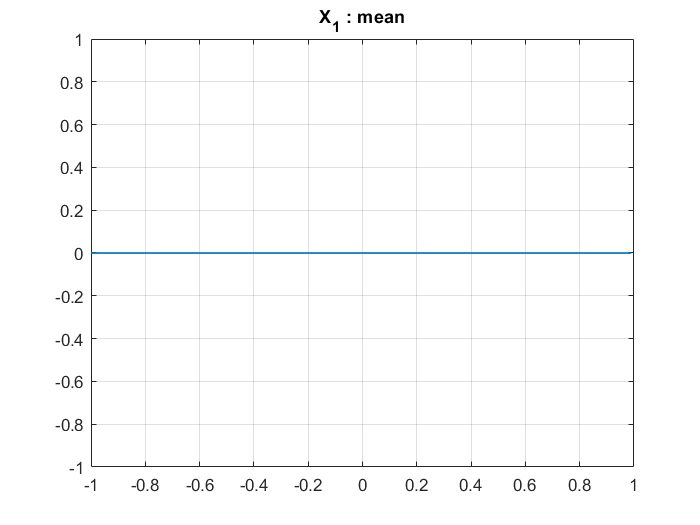

x1_dasti = zeros(Lt,1);

plot(t,x1_dasti,'linewidth', 1);
title('X_1 : mean');
grid on;

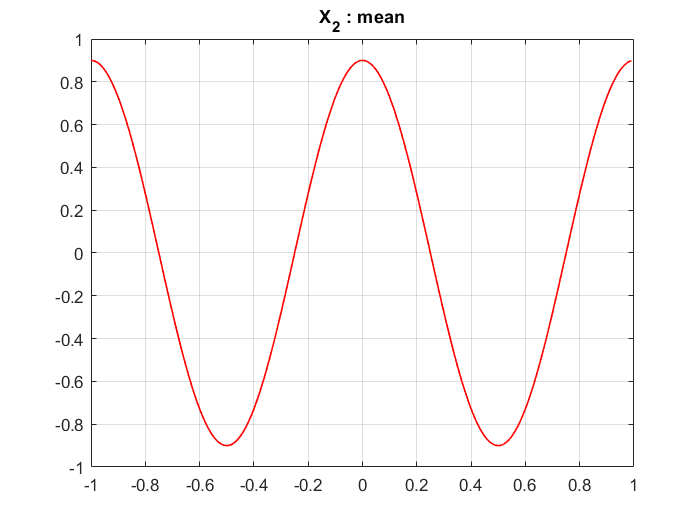


x2_dasti = (2/pi)* (sin(2*pi*t + pi/4) - sin(2*pi*t - pi/4));

plot(t,x2_dasti, 'r', 'linewidth', 1);
title('X_2 : mean');
grid on;

## `Part 5 :`

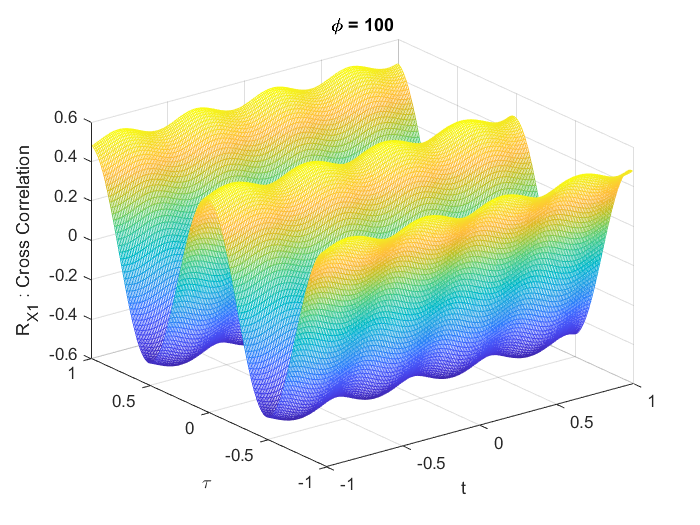

Rx1_n1 = zeros(Lt,Lt,length(phi1_n1));
Rx1_n2 = zeros(Lt,Lt,length(phi1_n2));

Rx2_n1 = zeros(Lt,Lt,length(phi2_n1));
Rx2_n2 = zeros(Lt,Lt,length(phi2_n2));

for i = 1:Lt
    for j = 1:Lt
        Rx1_n1(i,j,:) = cos((2*pi*t(i))+phi1_n1).*cos((2*pi*(t(i)+t(j))+phi1_n1));
        Rx1_n2(i,j,:) = cos((2*pi*t(i))+phi1_n2).*cos((2*pi*(t(i)+t(j))+phi1_n2));
        
        Rx2_n1(i,j,:) = cos((2*pi*t(i))+phi2_n1).*cos((2*pi*(t(i)+t(j))+phi2_n1));
        Rx2_n2(i,j,:) = cos((2*pi*t(i))+phi2_n2).*cos((2*pi*(t(i)+t(j))+phi2_n2));
    end
end

Rx1_n1_mean = zeros(Lt,Lt,1);
Rx1_n2_mean = zeros(Lt,Lt,1);

Rx2_n1_mean = zeros(Lt,Lt,1);
Rx2_n2_mean = zeros(Lt,Lt,1);

for i = 1:Lt
    for j = 1:Lt
        Rx1_n1_mean(i,j) = sum(Rx1_n1(i,j,:))/length(phi1_n1);
        Rx1_n2_mean(i,j) = sum(Rx1_n2(i,j,:))/length(phi1_n2);
        
        Rx2_n1_mean(i,j) = sum(Rx2_n1(i,j,:))/length(phi2_n1);
        Rx2_n2_mean(i,j) = sum(Rx2_n2(i,j,:))/length(phi2_n2);
    end
end

mesh(t,t,Rx1_n1_mean');
title("\phi = 100");
xlabel("t");
ylabel("\tau");
zlabel("R_X_1 : Cross Correlation");

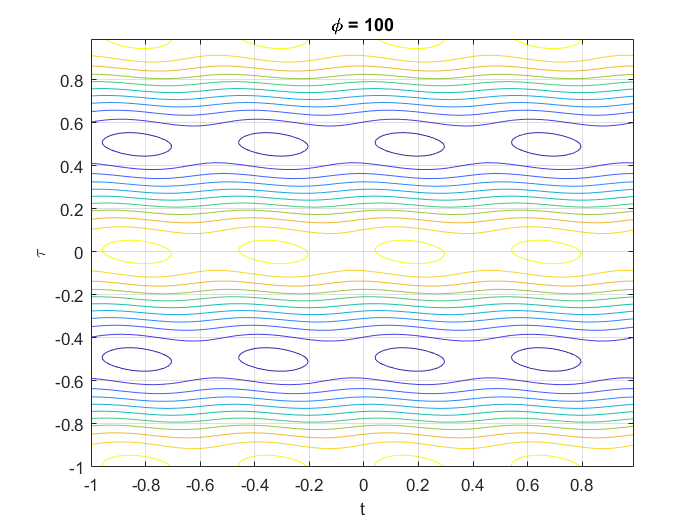

contour(t,t,Rx1_n1_mean');
title("\phi = 100");
xlabel("t");
ylabel("\tau");
grid on;

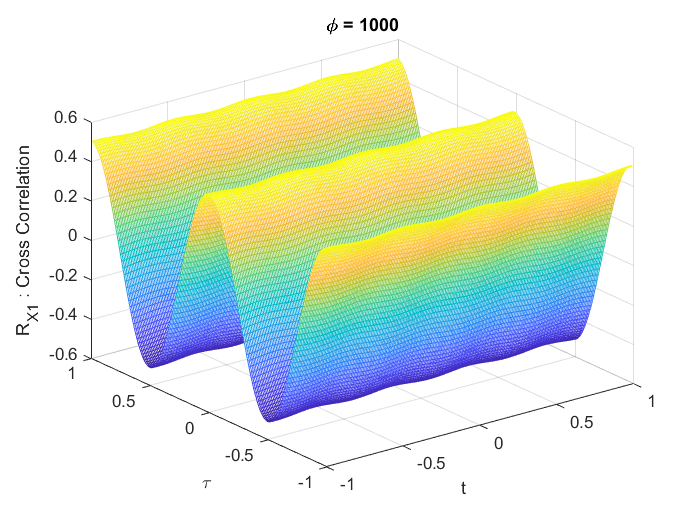


mesh(t,t,Rx1_n2_mean');
title("\phi = 1000");
xlabel("t");
ylabel("\tau");
zlabel("R_X_1 : Cross Correlation");

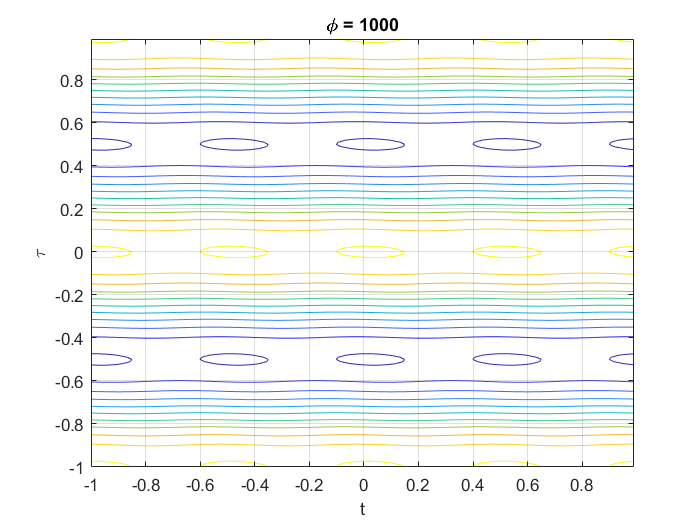

contour(t,t,Rx1_n2_mean');
title("\phi = 1000");
xlabel("t");
ylabel("\tau");
grid on;

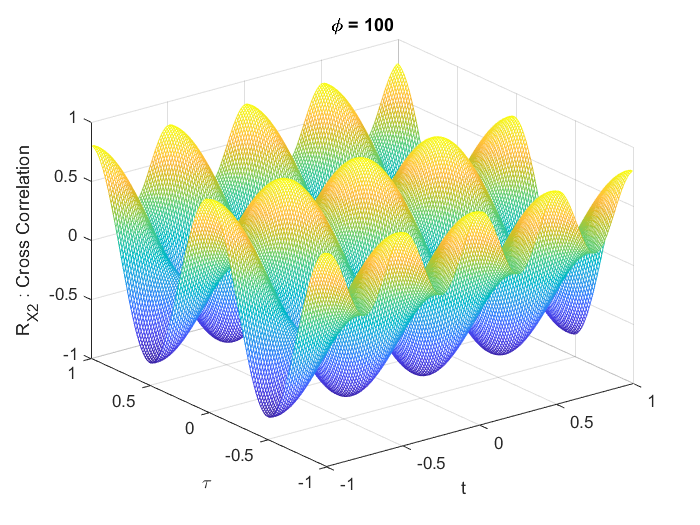


mesh(t,t,Rx2_n1_mean');
title("\phi = 100");
xlabel("t");
ylabel("\tau");
zlabel("R_X_2 : Cross Correlation");

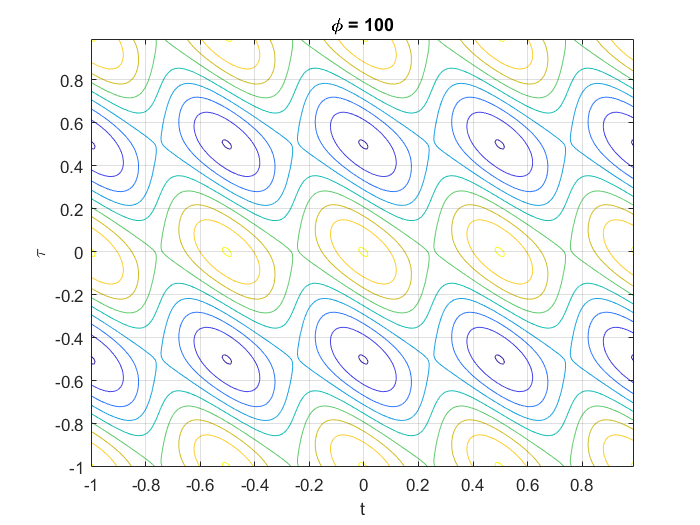

contour(t,t,Rx2_n1_mean');
title("\phi = 100");
xlabel("t");
ylabel("\tau");
grid on;

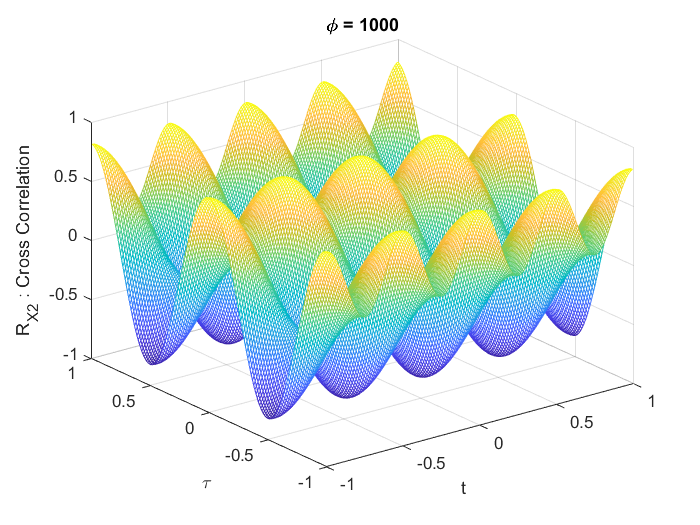


mesh(t,t,Rx2_n2_mean');
title("\phi = 1000");
xlabel("t");
ylabel("\tau");
zlabel("R_X_2 : Cross Correlation");

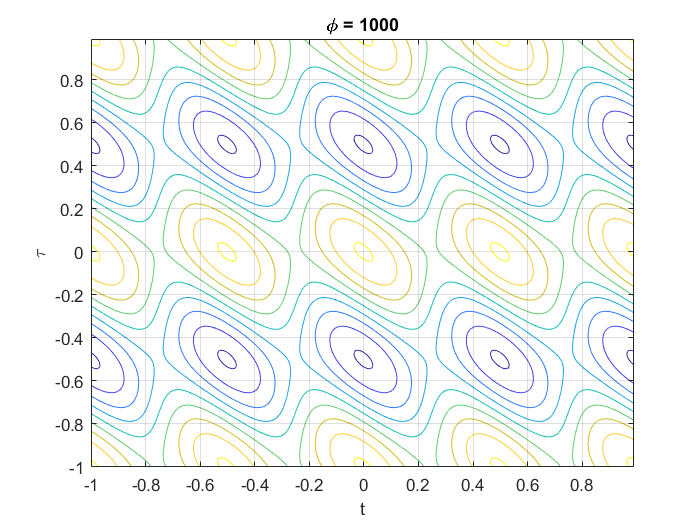

contour(t,t,Rx2_n2_mean');
title("\phi = 1000");
xlabel("t");
ylabel("\tau");
grid on;

## `Part 6 :`

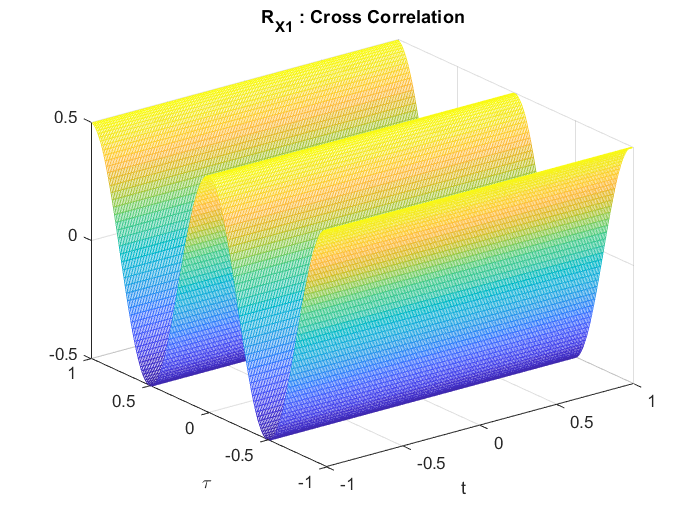

Rx1_dasti = zeros(Lt,Lt);

v=(1/2)*cos(2*pi*t);
for i = 1:Lt
    Rx1_dasti(i,:) = v;
end

Rx2_dasti = zeros(Lt,Lt);
for i=1:Lt
    for j=1:Lt
        Rx2_dasti(i,j)=(1/pi)*cos(2*pi*(2*t(i)+t(j)))+(1/2)*cos(2*pi*t(j));
    end
end

mesh(t,t,Rx1_dasti');
title("R_X_1 : Cross Correlation");
xlabel("t");
ylabel("\tau");

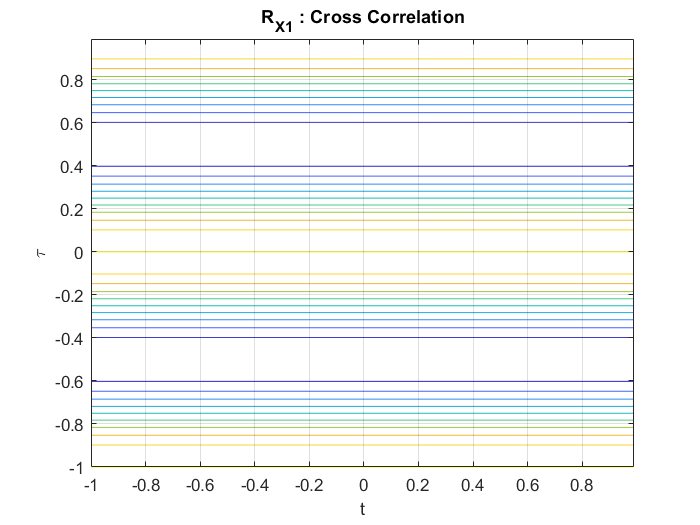

contour(t,t,Rx1_dasti');
title("R_X_1 : Cross Correlation");
xlabel("t");
ylabel("\tau");
grid on;

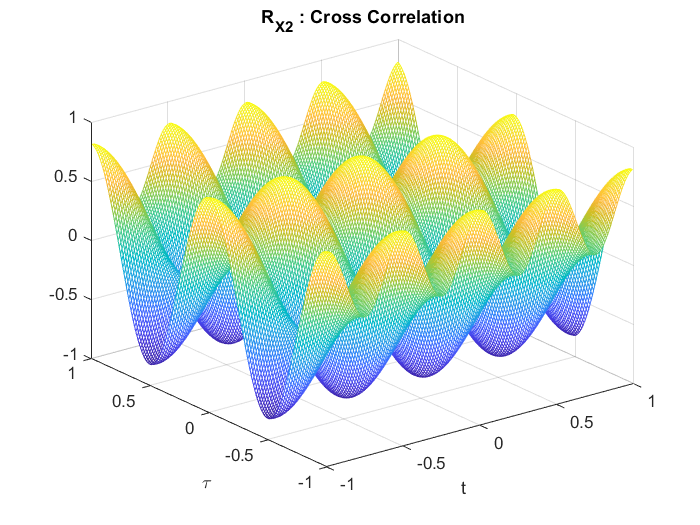


mesh(t,t,Rx2_dasti');
title("R_X_2 : Cross Correlation");
xlabel("t");
ylabel("\tau");

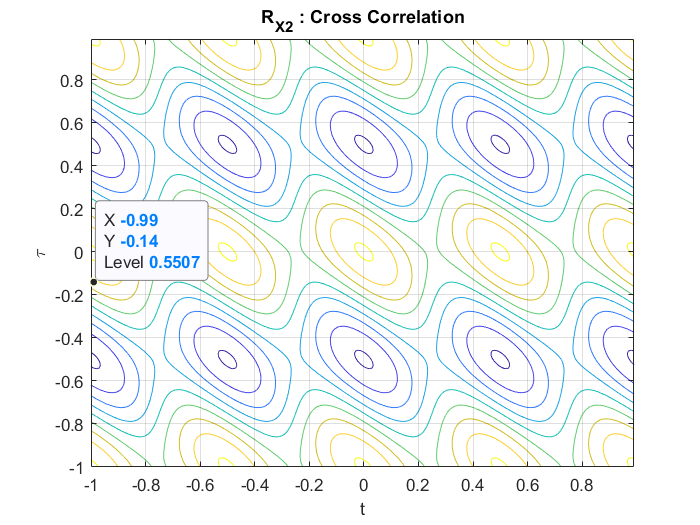

contour(t,t,Rx2_dasti');
title("R_X_2 : Cross Correlation");
xlabel("t");
ylabel("\tau");
grid on;

# `My Functions :`

function  RContour(X,Y,t1,t2)
    contour(t1,t2,Y'*X,'linewidth', 2);
    grid on;
end

## `Part 1.3 :`

function out= Pr(X,Y)
    a(1,:) = X(:);
    a(2,:) = Y(:);
    prob = zeros(1);
    j=1;
    for i = 1:3000
        if a(2,i)>0.2 && a(2,i) <0.8
            prob(1,j) = a(1,i);
            j=j+1;
        end
    end
    out=prob;
end